## Punto 4

- Primero ejecutar el archivo IIR_Design

- Definir las ganancias deseadas

- Importar la entrada y cambiar el nombre del archivo en auidoread("name.wav")( Debe estar muestreado a 64 kHz)

- Si no se tiene una señal de entrada específica, se pueden utilizar señales de ejemplo al descomentarlas

### Definición de parámetros y entrada

% Cuarto Punto
t = 0:1/fs:1; % Tiempo de 1 segundo

% Definición de la ganacia 
G1 = 0.25;
G2 = 0.5;
G3 = 1;
G4 = 2;

%=============== Eliga la entrada deseada


X = sin(2*pi*20*t) + sin(2*pi*700*t) + sin(2*pi*3000*t) + sin(2*pi*10000*t) + sin(2*pi*200*t) + sin(2*pi*1000*t) + sin(2*pi*6000*t) +sin(2*pi*18000*t) ; % Señal de entrada con múltiples senoidales


%X = chirp(t, 20, t(end), fs/2);   % 20 Hz → 32 kHz


% [X, fs] = audioread("Ikkimel_WHOS_THAT.wav");   % audio File
% if size(X,2) > 1
%     X = mean(X, 2);% Convert to mono
% end


%X = sin(2*pi*1000*t); % Señal de entrada (1 kHz)


%X = randn(64000,1);  % white Gaussian noise


%X = zeros(64000,1);% Impulse
%X(1) = 1;% Impulse


audiowrite('beforeIIR.wav', X, fs);

### Espectro señal de entrada

% --- SNIPPET: espectro de entrada en dBFS (0 dB => tono amplitude 1) ---
% Asume X y fs definidos. X debe estar en rango [-1,1] si quieres dBFS real.
X = X(:);
N = length(X);           % usa la longitud real o un Nfft mayor si quieres interpolar
Nfft = fs;             % resolución en frecuencia (puedes ajustar)
half = 1:floor(Nfft/2)+1;
f_pos = (0:Nfft/2)*(fs/Nfft);

% FFT
X_fft = fft(X, Nfft);

% Single-sided magnitude normalizada para que un tono a amp=1 -> 1 (0 dB)
X_mag_single = abs(X_fft(half)) * (2 / N);   % IMPORTANT: dividir por N, multiplicar por 2
% Ajuste: si DC o Nyquist presentes, no doble esos bins (no crítico para tono no-DC)

% Convertir a dBFS
X_mag_dbFS = 20*log10(X_mag_single + eps);

% Encontrar pico
[peak_mag, idxPeak] = max(X_mag_single);
peak_freq = f_pos(idxPeak);
peak_mag_dbFS = X_mag_dbFS(idxPeak);

fprintf('Entrada: pico = %.6g (linear), %.2f dBFS en %.2f Hz\n', peak_mag, peak_mag_dbFS, peak_freq);

Entrada: pico = 0.999984 (linear), -0.00 dBFS en 3000.00 Hz


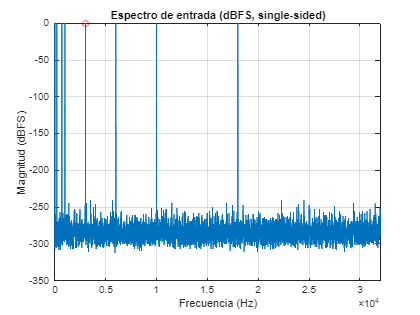


% Plot
figure;
plot(f_pos, X_mag_dbFS, 'LineWidth',1); grid on;
xlabel('Frecuencia (Hz)'); ylabel('Magnitud (dBFS)');
title('Espectro de entrada (dBFS, single-sided)');
xlim([0 fs/2]);
hold on; plot(peak_freq, peak_mag_dbFS, 'ro'); hold off;

## Primera Etapa - aplicación de cada filtro a la entrada


% Sistema con filtros FIR
[b1_bil, a1_bil] = zp2tf(zd1, pd1, kd1)

b1_bil = 1.0e-05 *

    0.1388    0.4165    0.4165    0.1388


a1_bil =     1.0000   -2.9550    2.9111   -0.9560


[b2_bil, a2_bil] = zp2tf(zd2, pd2, kd2)

b2_bil = 1.0e-03 *

    0.0829         0   -0.2487         0    0.2487         0   -0.0829


a2_bil =     1.0000   -5.8131   14.0895  -18.2255   13.2703   -5.1568    0.8356


[b3_bil, a3_bil] = zp2tf(zd3, pd3, kd3)

b3_bil =     0.0070         0   -0.0210         0    0.0210         0   -0.0070


a3_bil =     1.0000   -4.9753   10.4678  -11.9403    7.7965   -2.7639    0.4154


[b4_bil, a4_bil] = zp2tf(zd4, pd4, kd4)

b4_bil =     0.5740   -1.7221    1.7221   -0.5740


a4_bil =     1.0000   -1.9158    1.3470   -0.3293




% Se utiliza filtfilt, algoritmo de fase cero para IIRs.
y1 = filtfilt(b1_bil, a1_bil, X);
y2 = filtfilt(b2_bil, a2_bil, X);
y3 = filtfilt(b3_bil, a3_bil, X);
y4 = filtfilt(b4_bil, a4_bil, X);


### Respuestas en magnitud y fase de cada filtro ante la entrada

y1: salida max @ 20.0 Hz = -0.00 dBFS (atenuación 0.00 dB)


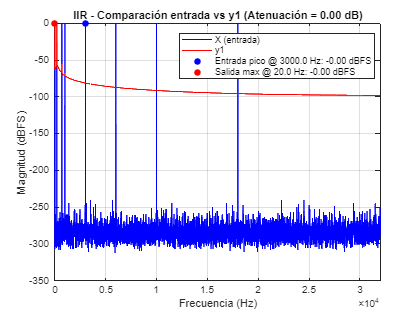

y2: salida max @ 700.0 Hz = -0.02 dBFS (atenuación 0.02 dB)


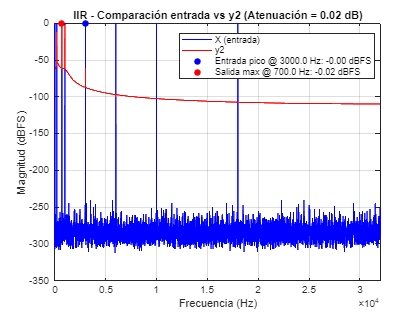

y3: salida max @ 3000.0 Hz = -0.00 dBFS (atenuación 0.00 dB)


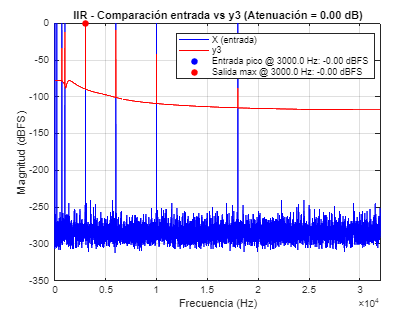

y4: salida max @ 18000.0 Hz = -0.00 dBFS (atenuación 0.00 dB)


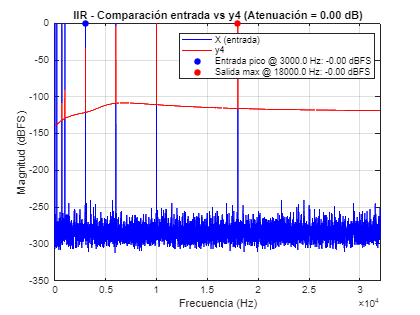

%% --- SNIPPET: espectro de salida para y1, y2, y3, y4 ---
% Usa: X, fs, y1..y4, Nfft, peak_freq, peak_mag_dbFS, f_pos, half

Ys = {y1(:), y2(:), y3(:), y4(:)};
names = {'y1','y2','y3','y4'};
for k = 1:4
    y = Ys{k};  % vector columna

    % FFT con mismo Nfft que la entrada
    Y_fft = fft(y, Nfft);

    % Single-sided magnitude
    Y_mag_single = abs(Y_fft(half)) * (2 / length(y));
    Y_mag_dbFS   = 20*log10(Y_mag_single + eps);

    % Magnitud a la frecuencia del pico de entrada (solo para referencia)
    Y_mag_at_peak = interp1(f_pos, Y_mag_single, peak_freq, 'linear', 'extrap');
    Y_mag_at_peak_dbFS = 20*log10(Y_mag_at_peak + eps);

    % Nuevo: valor máximo después del filtrado
    [Y_max_dbFS, idx_max] = max(Y_mag_dbFS);
    Y_max_freq = f_pos(idx_max);

    % Nueva atenuación: input_pico - output_max
    attenuation = peak_mag_dbFS - Y_max_dbFS;

    fprintf('%s: salida max @ %.1f Hz = %.2f dBFS (atenuación %.2f dB)\n', ...
        names{k}, Y_max_freq, Y_max_dbFS, attenuation);

    % ----- Plot comparativo -----
    figure('Name', ['Entrada vs ' names{k}]);
    plot(f_pos, X_mag_dbFS, 'b', 'LineWidth', 1); hold on;
    plot(f_pos, Y_mag_dbFS, 'r', 'LineWidth', 1);

    % Punto de referencia del input en el pico
    plot(peak_freq, peak_mag_dbFS, 'bo', 'MarkerFaceColor','b');

    % Nuevo: punto máximo del filtro
    plot(Y_max_freq, Y_max_dbFS, 'ro', 'MarkerFaceColor','r');

    legend('X (entrada)', names{k}, ...
           sprintf('Entrada pico @ %.1f Hz: %.2f dBFS', peak_freq, peak_mag_dbFS), ...
           sprintf('Salida max @ %.1f Hz: %.2f dBFS', Y_max_freq, Y_max_dbFS), ...
           'Location', 'Best');

    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud (dBFS)');
    title(sprintf('IIR - Comparación entrada vs %s (Atenuación = %.2f dB)', ...
        names{k}, attenuation));
    grid on; xlim([0 fs/2]);

    saveas(gcf,['espectro' names{k} '.png'])
end

## Segunda Etapa - Cambio de Amplitud por ganancias G1, G2, G3 y G4 


yG1 = y1 * G1;
yG2 = y2 * G2;
yG3 = y3 * G3;
yG4 = y4 * G4;

### Comparación de Espectros en la segunda etapa

yG1: salida max @ 20.0 Hz = -12.04 dBFS (atenuación 12.04 dB) | G = 0.250 (-12.04 dB)


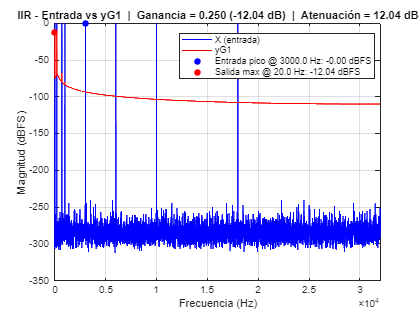

yG2: salida max @ 700.0 Hz = -6.05 dBFS (atenuación 6.05 dB) | G = 0.500 (-6.02 dB)


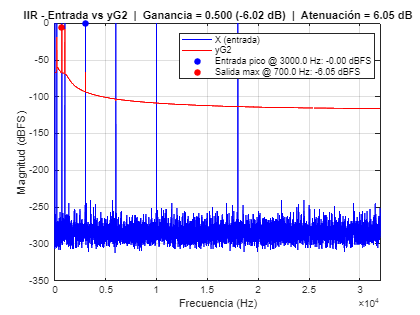

yG3: salida max @ 3000.0 Hz = -0.00 dBFS (atenuación 0.00 dB) | G = 1.000 (0.00 dB)


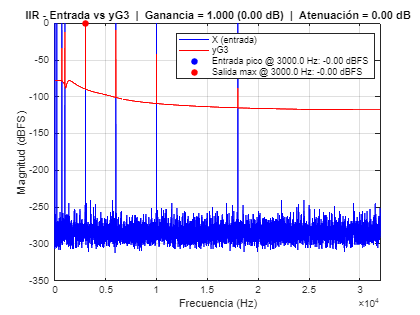

yG4: salida max @ 18000.0 Hz = 6.02 dBFS (atenuación -6.02 dB) | G = 2.000 (6.02 dB)


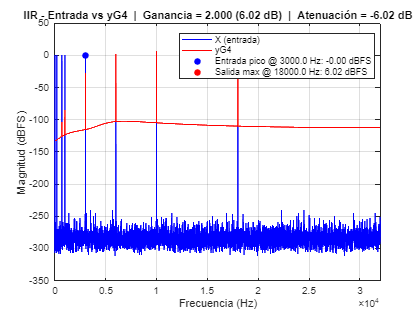

Ys = {yG1(:), yG2(:), yG3(:), yG4(:)};
names = {'yG1','yG2','yG3','yG4'};
gains = [G1,G2,G3,G4];
for k = 1:4
    y = Ys{k};  % vector columna

    % FFT con mismo Nfft que la entrada
    Y_fft = fft(y, Nfft);

    % Single-sided magnitude
    Y_mag_single = abs(Y_fft(half)) * (2 / length(y));
    Y_mag_dbFS   = 20*log10(Y_mag_single + eps);

    % Referencia: magnitud de la entrada en la frecuencia del pico
    Y_mag_at_peak = interp1(f_pos, Y_mag_single, peak_freq, 'linear', 'extrap');
    Y_mag_at_peak_dbFS = 20*log10(Y_mag_at_peak + eps);

    % Magnitud máxima de la salida filtrada
    [Y_max_dbFS, idx_max] = max(Y_mag_dbFS);
    Y_max_freq = f_pos(idx_max);

    % Atenuación basada en máximo
    attenuation = peak_mag_dbFS - Y_max_dbFS;

    % Ganancia actual
    G_lin = gains(k);
    G_dB  = 20*log10(G_lin);

    fprintf('%s: salida max @ %.1f Hz = %.2f dBFS (atenuación %.2f dB) | G = %.3f (%.2f dB)\n', ...
        names{k}, Y_max_freq, Y_max_dbFS, attenuation, G_lin, G_dB);

    % ----- Plot comparativo -----
    figure('Name', ['Entrada vs ' names{k}]);
    plot(f_pos, X_mag_dbFS, 'b', 'LineWidth', 1); hold on;
    plot(f_pos, Y_mag_dbFS, 'r', 'LineWidth', 1);

    % Punto de entrada (pico)
    plot(peak_freq, peak_mag_dbFS, 'bo', 'MarkerFaceColor','b');

    % Punto máximo salida
    plot(Y_max_freq, Y_max_dbFS, 'ro', 'MarkerFaceColor','r');

    legend('X (entrada)', names{k}, ...
           sprintf('Entrada pico @ %.1f Hz: %.2f dBFS', peak_freq, peak_mag_dbFS), ...
           sprintf('Salida max @ %.1f Hz: %.2f dBFS', Y_max_freq, Y_max_dbFS), ...
           'Location', 'Best');

    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud (dBFS)');

    % Nuevo: título incluye ganancia lineal y en dB
    title(sprintf('IIR - Entrada vs %s  |  Ganancia = %.3f (%.2f dB)  |  Atenuación = %.2f dB', ...
        names{k}, G_lin, G_dB, attenuation));

    grid on; xlim([0 fs/2]);
    saveas(gcf,['espectro' names{k} '.png'])
end

## Tercera Etapa - Y_final (sumador)

%Ganancias + sumador
y_final = yG1 + yG2 + yG3 + yG4;


Ys = {y_final(:)};
names = {'y_{final}'};

k=1

k = 1

    y = Ys{k};  % vector columna

    % FFT con mismo Nfft que la entrada
    Y_fft = fft(y, Nfft);

    % Single-sided magnitude
    Y_mag_single = abs(Y_fft(half)) * (2 / length(y));
    Y_mag_dbFS   = 20*log10(Y_mag_single + eps);

    % Magnitud a la frecuencia del pico de entrada (solo para referencia)
    Y_mag_at_peak = interp1(f_pos, Y_mag_single, peak_freq, 'linear', 'extrap');
    Y_mag_at_peak_dbFS = 20*log10(Y_mag_at_peak + eps);

    % Nuevo: valor máximo después del filtrado
    [Y_max_dbFS, idx_max] = max(Y_mag_dbFS);
    Y_max_freq = f_pos(idx_max);

    % Nueva atenuación: input_pico - output_max
    attenuation = peak_mag_dbFS - Y_max_dbFS;

    fprintf('%s: salida max @ %.1f Hz = %.2f dBFS (atenuación %.2f dB)\n', ...
        names{k}, Y_max_freq, Y_max_dbFS, attenuation);

y_{final}: salida max @ 18000.0 Hz = 6.02 dBFS (atenuación -6.02 dB)


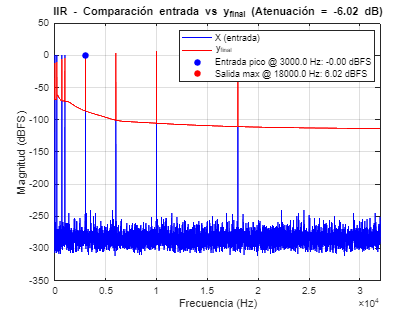


    % ----- Plot comparativo -----
    figure('Name', ['Entrada vs ' names{k}]);
    plot(f_pos, X_mag_dbFS, 'b', 'LineWidth', 1); hold on;
    plot(f_pos, Y_mag_dbFS, 'r', 'LineWidth', 1);

    % Punto de referencia del input en el pico
    plot(peak_freq, peak_mag_dbFS, 'bo', 'MarkerFaceColor','b');

    % Nuevo: punto máximo del filtro
    plot(Y_max_freq, Y_max_dbFS, 'ro', 'MarkerFaceColor','r');

    legend('X (entrada)', names{k}, ...
           sprintf('Entrada pico @ %.1f Hz: %.2f dBFS', peak_freq, peak_mag_dbFS), ...
           sprintf('Salida max @ %.1f Hz: %.2f dBFS', Y_max_freq, Y_max_dbFS), ...
           'Location', 'Best');

    xlabel('Frecuencia (Hz)');
    ylabel('Magnitud (dBFS)');
    title(sprintf('IIR - Comparación entrada vs %s (Atenuación = %.2f dB)', ...
        names{k}, attenuation));
    grid on; xlim([0 fs/2]);

    saveas(gcf,['espectro' names{k} '.png'])

% Normalize to prevent clipping (optional but safe)
y_final = y_final / max(abs(y_final));

% Save filtered output to a new audio file
audiowrite("AfterIIR.wav", y_final, fs);



